# Problema 9

Functia Bessel de ordin n => $J_n \left(x\right)=\frac{1}{\pi }\int_0^{\pi } \cos \left(\textrm{xsin}\theta -n\theta \right)\;d\theta$ 

Functia Bessel de ordin 0 => $J_0 \left(x\right)=\sum_{k=0}^{\infty } \frac{{\left(-1\right)}^k }{{\left(k!\right)}^2 }{\left(\frac{x}{2}\right)}^{2k}$  

Inlocuim x cu 2x => $J_0 \left(2x\right)=\sum_{k=0}^{\infty } \frac{{\left(-1\right)}^k }{{\left(k!\right)}^2 }x^{2k}$ 

% Definirea seriei Maclaurin pentru J0(2x)
function J = bessel_J0_Maclaurin(x, n_terms)
    J = 0;
    for m = 0:n_terms
        J = J + ((-1)^m / (factorial(m)^2)) * (x^(2*m)); 
    end
end

function [R, a, b] = pade_approximation(coeff, m, k, x)
    required_length = m + k + 1;

    if length(coeff) < required_length
        error('Vectorul coeff nu are suficienti termeni. Crește max_order.');
    end

    % Construim sistemul de ecuații pentru coeficienții b_j
    C = zeros(k, k);
    for row = 1:k
        idx_start = m + row;
        idx_end = max(1, m + row - k + 1);
        
        % Asigurăm indexare corectă
        range = idx_start:-1:idx_end;
        C(row, 1:length(range)) = coeff(range);
    end

    d = -coeff(m+1:m+k)';  % Partea dreaptă a sistemului

    % Stabilizare numerică cu pseudo-inversă
    b = pinv(C) * d;  
    b = [1; b]; % Adăugăm b0 = 1

    % Calculăm coeficienții a_i
    a = zeros(m+1,1);
    for j = 0:m
        sum_ab = 0;
        for ell = 0:min(j,k)
            sum_ab = sum_ab + coeff(j-ell+1) * b(ell+1);
        end
        a(j+1) = sum_ab;
    end
    
    % Construim funcția rațională R_{m,k}(x)
    Px = polyval(flipud(a), x);
    Qx = polyval(flipud(b), x);
    R = Px ./ Qx;
 
end

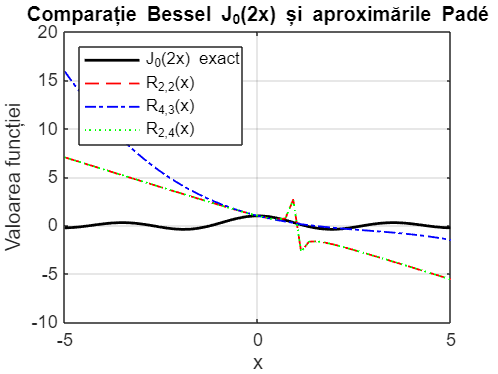

% Domeniul de reprezentare
x = linspace(-5, 5, 50);  % Interval mai restrâns pentru claritate

% Calculul exact al funcției Bessel
J0_exact = besselj(0,2*x);

% Generăm coeficienții seriei Maclaurin pentru J0(2x)
max_order = 14;  % Creștem numărul de termeni pentru stabilitate
coeff = zeros(1, max_order);
for idx = 0:max_order-1
    coeff(idx+1) = ((-1)^idx) / ((factorial(idx))^2); % Corectare coeficienți
end

% Calculăm aproximările Padé
[R22, ~, ~] = pade_approximation(coeff,2,2,x);
[R43, ~, ~] = pade_approximation(coeff,4,3,x);
[R24, ~, ~] = pade_approximation(coeff,2,4,x);


% Grafic comparativ
figure;
plot(x,J0_exact,'k','LineWidth',1.5); hold on;
plot(x,R22,'--r','LineWidth',1);
plot(x,R43,'-.b','LineWidth',1);
plot(x,R24,':g','LineWidth',1);

legend('J_0(2x) exact','R_{2,2}(x)','R_{4,3}(x)','R_{2,4}(x)', 'Location', 'NorthWest');
xlabel('x');
ylabel('Valoarea funcției');
title('Comparație Bessel J_0(2x) și aproximările Padé');
grid on;